ig_big = image_geom('nx', 512, 'fov', 32, 'down', 1);
sg = sino_geom('ge1', 'units', 'cm', 'strip_width', 'd', 'down', 1);
geom = fbp2(sg, ig_big);
Abig = Gtomo_nufft_new(sg, ig_big);

Warn: Gtomo_nufft 157: todo: untested



Input = fbp2(input_image, geom);

fbp2_back_fan: 142 of 984 5.2
fbp2_back_fan: 279 of 984 5.3
fbp2_back_fan: 416 of 984 5.3
fbp2_back_fan: 558 of 984 5.3
fbp2_back_fan: 701 of 984 5.3
fbp2_back_fan: 848 of 984 5.3


Output = fbp2(output, geom);

fbp2_back_fan: 112 of 984 0.0
fbp2_back_fan: 205 of 984 0.0
fbp2_back_fan: 315 of 984 0.1
fbp2_back_fan: 424 of 984 0.1
fbp2_back_fan: 558 of 984 0.1
fbp2_back_fan: 690 of 984 0.1
fbp2_back_fan: 822 of 984 0.1
fbp2_back_fan: 945 of 984 0.1


ExpectedImage = fbp2(target_image, geom);

fbp2_back_fan: 134 of 984 0.0
fbp2_back_fan: 275 of 984 0.0
fbp2_back_fan: 423 of 984 0.1
fbp2_back_fan: 570 of 984 0.1
fbp2_back_fan: 698 of 984 0.1
fbp2_back_fan: 845 of 984 0.1


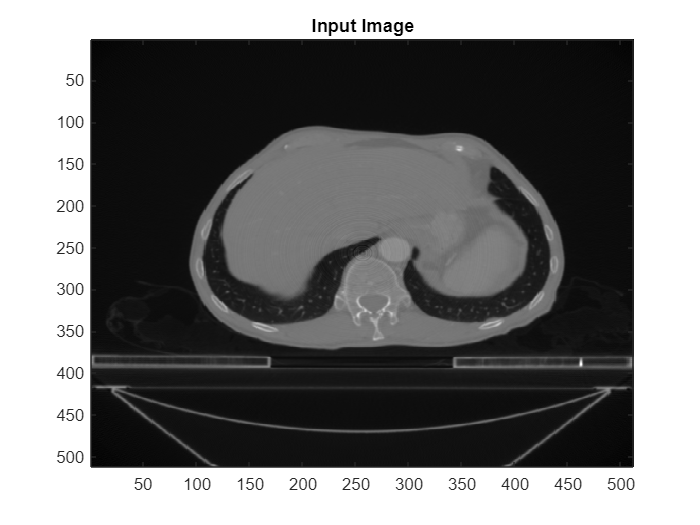


colormap gray;
imagesc(Input);
title('Input Image');

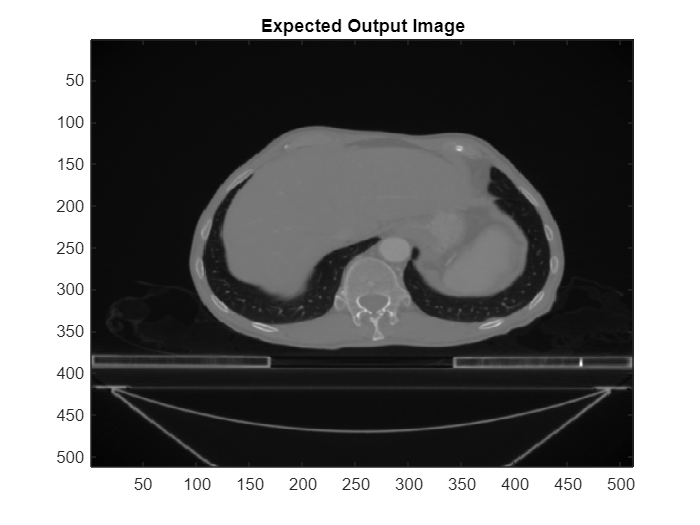

imagesc(ExpectedImage);
title('Expected Output Image');

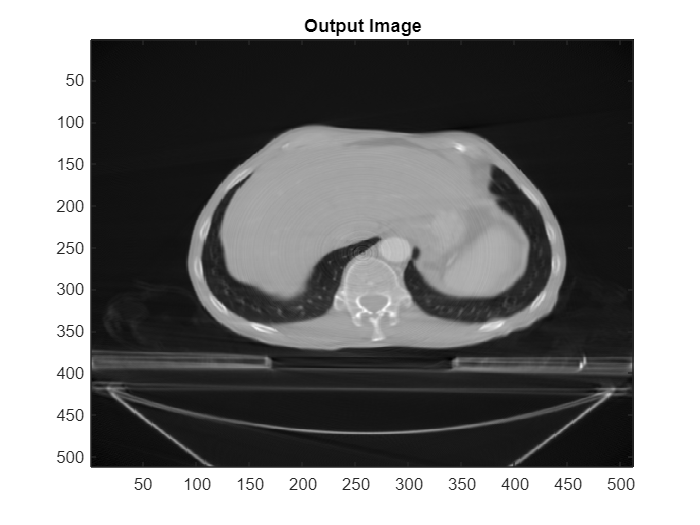

imagesc(Output);
title('Output Image');

colormap gray;

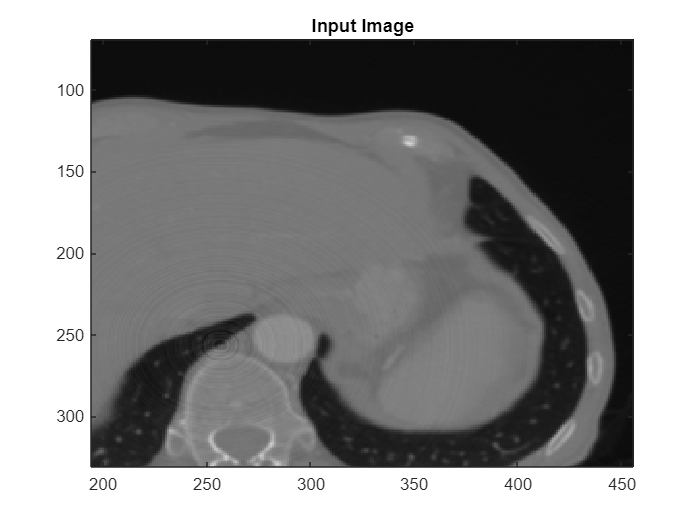

imagesc(Input);
title('Input Image');
xlim([194 456]);
ylim([69 331]);

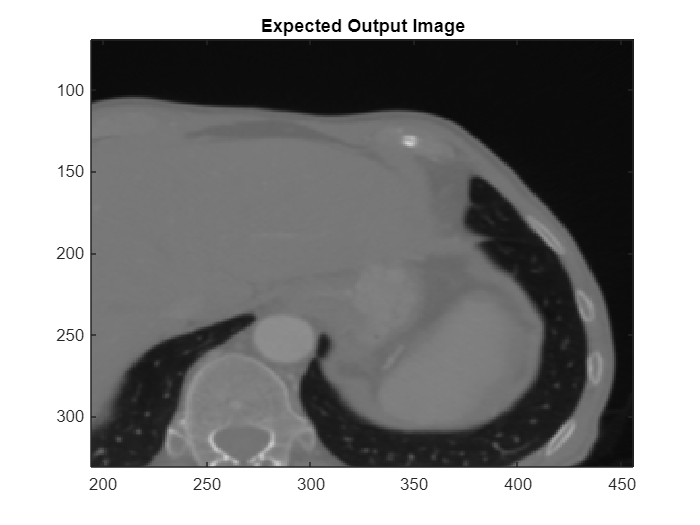

imagesc(ExpectedImage);
title('Expected Output Image');
xlim([194 456]);
ylim([69 331]);

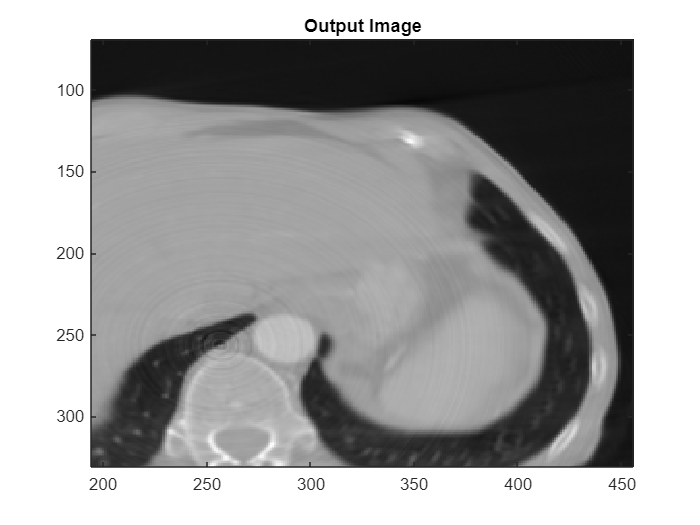

imagesc(Output);
title('Output Image');
xlim([194 456]);
ylim([69 331]);

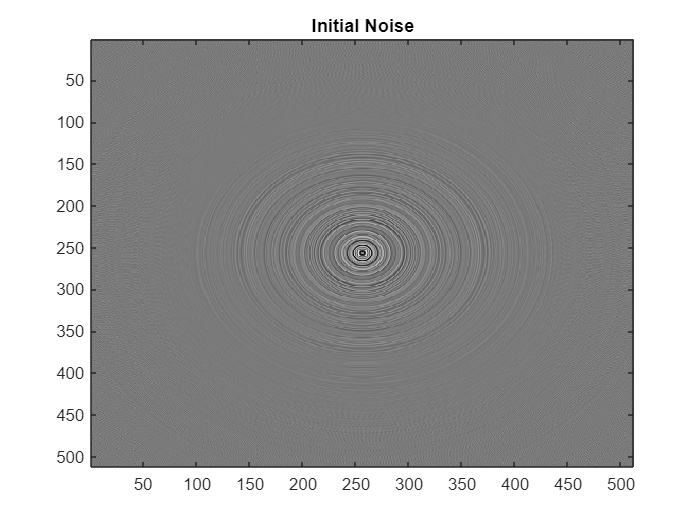

imagesc(Input - ExpectedImage);
title('Initial Noise');

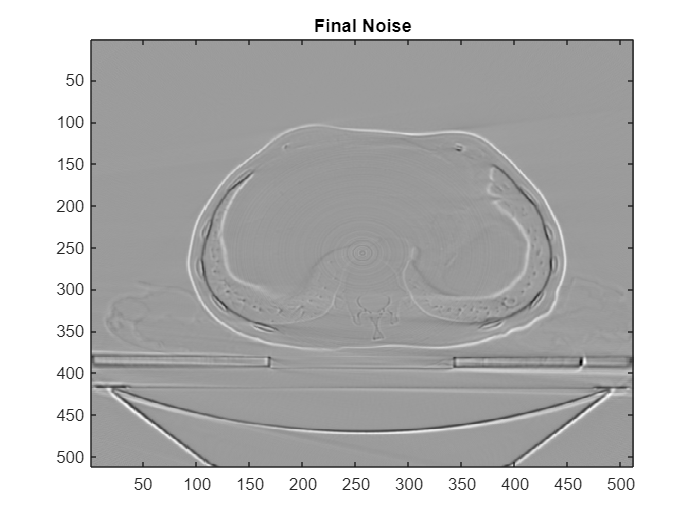

imagesc(Output - ExpectedImage);
title('Final Noise');